# Optima Bodluv

option = "Trias";

## Level Effektoren Blau

"Welcher blaue Effektor hat gegen welche Bedrohung (rote Systeme) wie performt?"

sheetName = "red_air_killed_by_effector";
data = importData(sheetName, option);
dataVar = "InDeployedREDAIR";

#### Performanz pro Effektor blau

grpVar = "BlueEffector";
univarStats(data, grpVar, dataVar);

#### Performanz pro Effektor blau und System rot

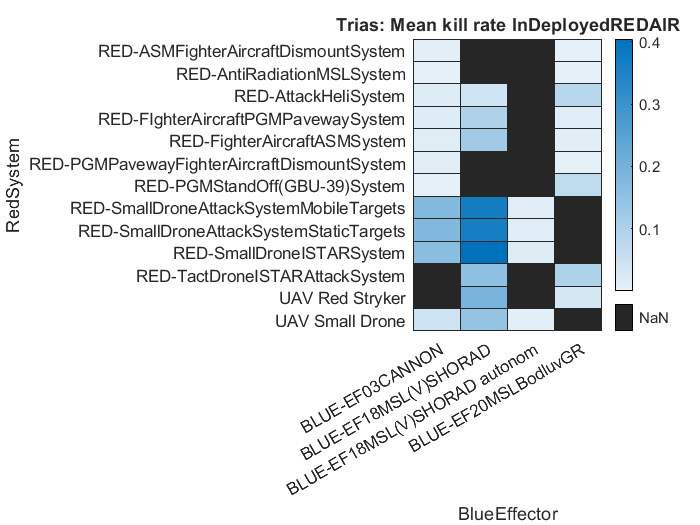

grpVar = ["BlueEffector"; "RedSystem"];
grpHeatmap(data, grpVar, dataVar, option, "PerformanceEffektorBlau", "Mean kill rate");

## Level Systeme Blau

"Welches blaue System hat gegen welche Bedrohung (rote Systeme) wie performt?"

sheetName = "red_air_killed_by_system";
data = importData(sheetName, option);

#### Performanz pro System blau

grpVar = "BlueSystem";
univarStats(data, grpVar, dataVar);

#### Performanz pro System blau (Angreifer) und System rot

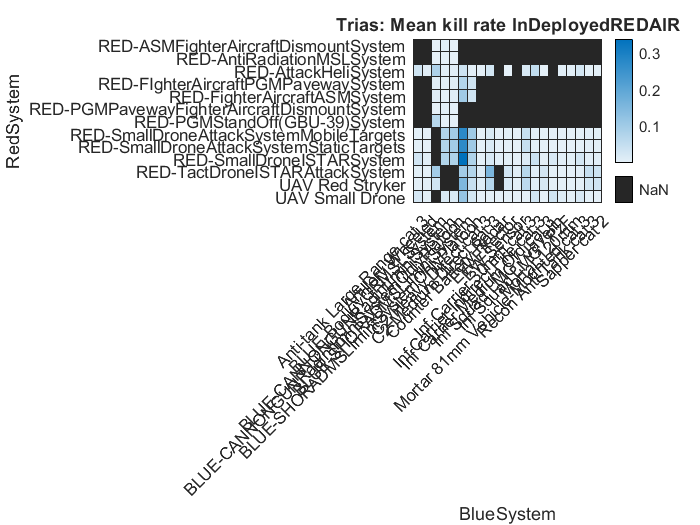

grpVar = ["BlueSystem"; "RedSystem"];
h = grpHeatmap(data, grpVar, dataVar, option, "PerformanceSystemBlau", "Mean kill rate");

## Level Systeme Rot

"Welches rote System hat gegen welches blaue System wie performt?"

sheetName = "blue_killed_by_red_system";
data = importData(sheetName, option);
dataVar = "InDeployedBLUE";

#### Performanz pro System rot

grpVar = "RedSystem";
univarStats(data, grpVar, dataVar);

#### Performanz pro System rot (Angreifer) und System blau

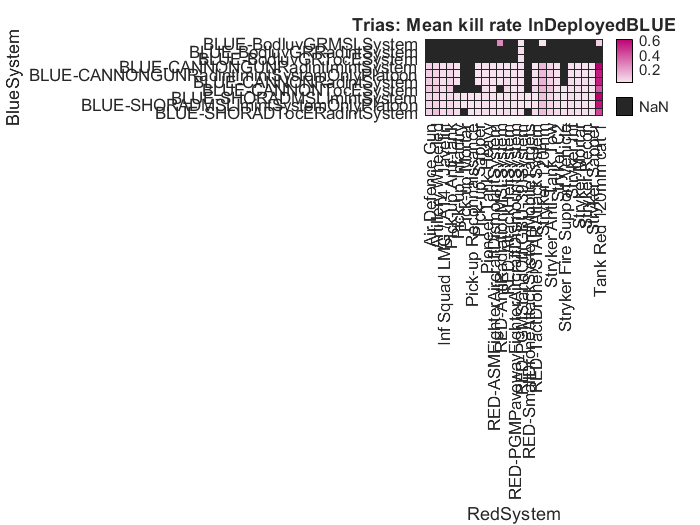

grpVar = ["RedSystem"; "BlueSystem"];
grpHeatmap(data, grpVar, dataVar, option, "PerformanceSystemRot", "Mean kill rate", h);

#### Anzahl verlorene Bodluv-Systeme

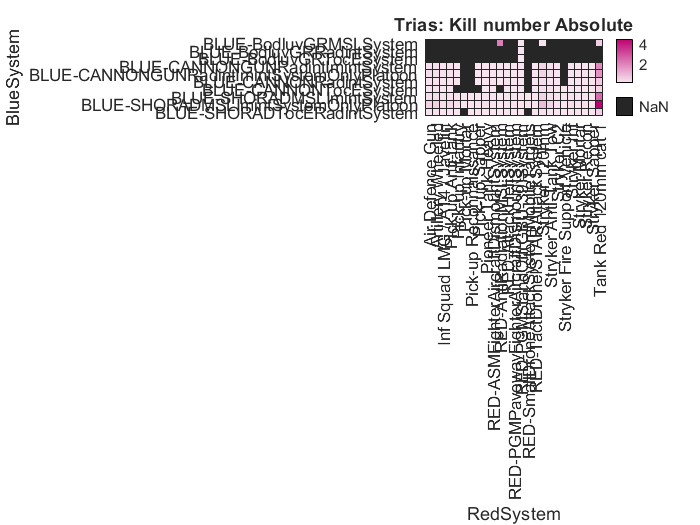

dataVar = "Absolute";
grpHeatmap(data, grpVar, dataVar, option, "PerformanceSystemRotAbsolut", "Kill number", h);

% saveResults("data")